% Start from here
addpath('./Skechers/');
load('./data/1DsktSample/1DsktSampleModel_small.mat');
B = [model.Omega_assemble.B ; model.Gamma_assemble.B]; 
d = [model.Omega_assemble.d ; model.Gamma_assemble.d];
[mB, nB] = size(B);
exact_problem.B = B;
exact_problem.d = d;

% Matrix properties
tic;
[lev_score, rank] = leverageScore(B);
exact_lev_time = toc

exact_lev_time = 0.1112

coh = max(lev_score);
if rank == nB
    fprintf('B is full rank, with coherence = %.4f.', coh);
end

B is full rank, with coherence = 0.9991.


% Solve exact problem
tic;
exact_problem.sol = B\d;
exact_problem.time = toc;
exact_problem.sparsity = nnz(B)/(mB*nB);
exact_problem.res = norm(B*exact_problem.sol-d);

abs_error = @(x) norm(model.u(x) - model.evaluate_LSFEM_elewise(x));
exact_problem.L2 = sqrt(integral(@(x) abs_error(x)^2, model.Omega(1), model.Omega(2), ...
                                    'ArrayValued', true, 'AbsTol', 1e-12));

% use a cell to store all the data for different sketchers
s = 1; p = lev_score/sum(lev_score); num_coworker = 10;
skt_ratios = [2,3,4,5,6,7,8,9,10];
sample_per_skt_coe = 100;

% Run model
Sketchers = cell(1,4); % {Gaussian, hashing, levScore, distlevScore};
h = waitbar(0, 'Processing...'); 
current_step = 0; total_steps = length(Sketchers) * length(skt_ratios) * sample_per_skt_coe;

for skt = 1:length(Sketchers)
    sketcher = struct();
    for j = 1:length(skt_ratios)
        skt_ratio = skt_ratios(j); mS = round(skt_ratio*nB);
        for i = 1:sample_per_skt_coe

            % construct sketcher S
            if skt == 1
                S = randn(mS, mB);
            elseif skt == 2
                S = sHashing(s,mS,mB,'Regular');
            elseif skt == 3
                S = leverageScoreSampling(mS,mB,p); 
            else
                [S, lev_time] = distributedLSS(mS,B,num_coworker);
                sketcher.lev_time(i,j) = max(lev_time);
            end
            
            tic; % sketching
            SB = S*B; Sd = S*d; 
            sketcher.sketch_time(i,j) = toc;

            tic; % solve
            sol = SB\Sd;
            sketcher.solve_time(i,j) = toc;

            % other statistics
            [mm, nn] = size(SB);
            sketcher.sparsity(i,j) = nnz(SB)/(mm*nn);
            sketcher.error(i,j) = norm(sol-exact_problem.sol);
            sketcher.res(i,j) = norm(B*sol-d);

            C_skt = model.reshape2mat(sol);
            abs_error = @(x) norm(model.u(x) - model.evaluate_LSFEM_elewise(x,C_skt));
            sketcher.L2(i,j) = sqrt(integral(@(x) abs_error(x)^2, model.Omega(1), model.Omega(2), ...
                                    'ArrayValued', true, 'AbsTol', 1e-12));

            current_step = current_step + 1;
            waitbar(current_step / total_steps, h);
        end
    end
    Sketchers{skt} = sketcher;
end
close(h);
%save('./data/1DsktSample/1DsktSampleResults_small_stat.mat', 'Sketchers');

% Start from here
load('./data/1DsktSample/1DsktSampleResults_small_stat.mat');
sketch_time = cellfun(@(x) x.sketch_time, Sketchers, 'UniformOutput', false);
solve_time = cellfun(@(x) x.solve_time, Sketchers, 'UniformOutput', false);
total_time = cellfun(@(x) x.solve_time + x.sketch_time, Sketchers, 'UniformOutput', false);
sparsity = cellfun(@(x) x.sparsity, Sketchers, 'UniformOutput', false);
x_error = cellfun(@(x) x.error, Sketchers, 'UniformOutput', false);
res = cellfun(@(x) x.res, Sketchers, 'UniformOutput', false);
L2 = cellfun(@(x) x.L2, Sketchers, 'UniformOutput', false);

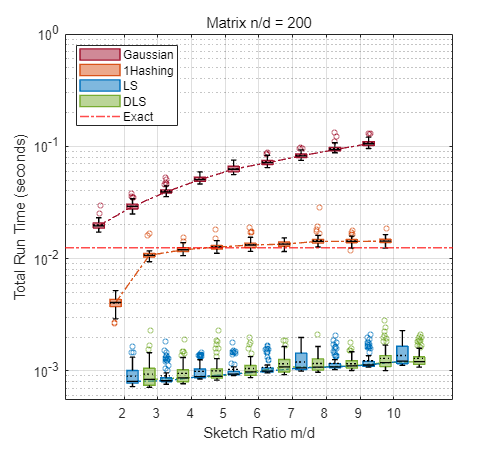

% Plot Run time
figure;
set(gcf,'position',[0, 0, 500, 450])
group_name = {'Gaussian','1Hashing', 'LS', 'DLS'};
color = [0.6350 0.0780 0.1840; 
         0.8500 0.3250 0.0980; 
         0 0.4470 0.7410; 
         0.4660 0.6740 0.1880];

h = daboxplot(total_time, ...
              'fill', 1, ...
              'linkline', 1, ...
              'legend', group_name, ...
              'boxalpha', 0.5, ...
              'mean', 1, ...
              'scatter', 0, ...
              'outliers', 1, ...
              'outsymbol', 'o', ...
              'boxwidth', 2.5, ...
              'boxspacing', 1.5, ...
              'colors', color, ...
              'xtlabels' , 2:10);

p = yline(exact_problem.time, ...
          'r-.', 'LineWidth', 1, ...
          'DisplayName', 'Exact');

box on; grid on;

ylim([0.00055, 1]);
set(gca, 'YScale', 'log');
set(h.ln, 'LineStyle', '-.', 'LineWidth', 1);
set(h.md, 'LineWidth', 1);
set(h.mn, 'LineWidth', 1);
set(h.lg, 'Location', 'northwest'); 
% set(h.lg, 'Position', [0.7, 0.7, 0.01, 0.01]); 

for i = 1:length(group_name)
    hScatter = h.ot(:,i);
    for j = 1:length(hScatter) 
        set(h.ot(j,i), 'CData', color(i,:));
        set(h.bx(j,i), 'LineWidth', 1, 'EdgeColor', color(i,:));
    end
end

xlabel("Sketch Ratio m/d");
ylabel("Total Run Time (seconds)");
title("Matrix n/d = 200"); %1000

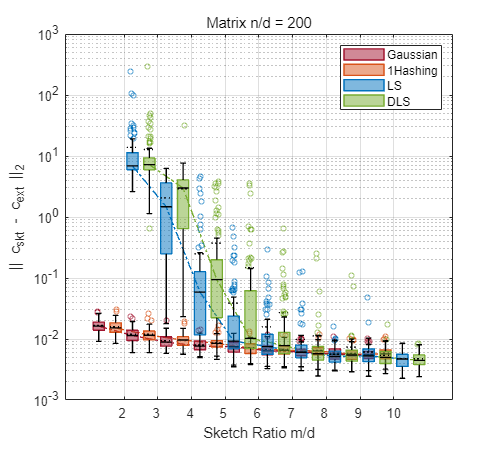

% x_error
figure;
set(gcf,'position',[0, 0, 500, 450])
group_name = {'Gaussian','1Hashing', 'LS', 'DLS'};
color = [0.6350 0.0780 0.1840; 
         0.8500 0.3250 0.0980; 
         0 0.4470 0.7410; 
         0.4660 0.6740 0.1880];

h = daboxplot(x_error, ...
              'fill', 1, ...
              'linkline', 1, ...
              'legend', group_name, ...
              'boxalpha', 0.5, ...
              'mean', 1, ...
              'scatter', 0, ...
              'outliers', 1, ...
              'outsymbol', 'o', ...
              'boxwidth', 2.5, ...
              'boxspacing', 1.5, ...
              'colors', color, ...
              'xtlabels' , 2:10);
box on; grid on;

%ylim([0.00068 0.5]);
set(gca, 'YScale', 'log');
set(h.ln, 'LineStyle', '-.', 'LineWidth', 1);
set(h.md, 'LineWidth', 1);
set(h.mn, 'LineWidth', 1);
set(h.lg, 'Location', 'northeast'); 
% set(h.lg, 'Position', [0.7, 0.7, 0.01, 0.01]); 

for i = 1:length(group_name)
    hScatter = h.ot(:,i);
    for j = 1:length(hScatter) 
        set(h.ot(j,i), 'CData', color(i,:));
        set(h.bx(j,i), 'LineWidth', 1, 'EdgeColor', color(i,:));
    end
end

xlabel("Sketch Ratio m/d");
ylabel("|| c_{skt} - c_{ext} ||_2");
title("Matrix n/d = 200"); %1000

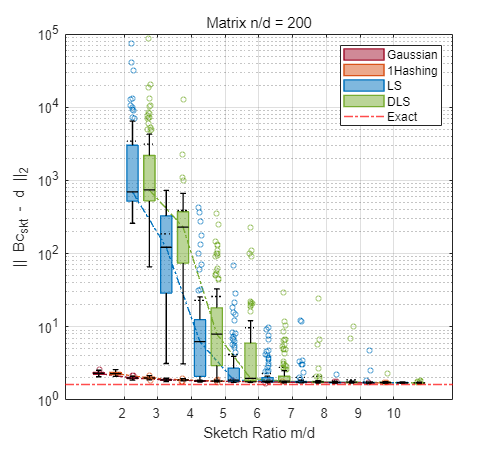

% Residual
figure;
set(gcf,'position',[0, 0, 500, 450])
group_name = {'Gaussian','1Hashing', 'LS', 'DLS'};
color = [0.6350 0.0780 0.1840; 
         0.8500 0.3250 0.0980; 
         0 0.4470 0.7410; 
         0.4660 0.6740 0.1880];

h = daboxplot(res, ...
              'fill', 1, ...
              'linkline', 1, ...
              'legend', group_name, ...
              'boxalpha', 0.5, ...
              'mean', 1, ...
              'scatter', 0, ...
              'outliers', 1, ...
              'outsymbol', 'o', ...
              'boxwidth', 2.5, ...
              'boxspacing', 1.5, ...
              'colors', color, ...
              'xtlabels' , 2:10);

p = yline(exact_problem.res, ...
          'r-.', 'LineWidth', 1, ...
          'DisplayName', 'Exact');
box on; grid on;

%ylim([0.00068 0.5]);
set(gca, 'YScale', 'log');
set(h.ln, 'LineStyle', '-.', 'LineWidth', 1);
set(h.md, 'LineWidth', 1);
set(h.mn, 'LineWidth', 1);
set(h.lg, 'Location', 'northeast'); 
% set(h.lg, 'Position', [0.7, 0.7, 0.01, 0.01]); 

for i = 1:length(group_name)
    hScatter = h.ot(:,i);
    for j = 1:length(hScatter) 
        set(h.ot(j,i), 'CData', color(i,:));
        set(h.bx(j,i), 'LineWidth', 1, 'EdgeColor', color(i,:));
    end
end

xlabel("Sketch Ratio m/d");
ylabel("|| Bc_{skt} - d ||_2");
title("Matrix n/d = 200"); %1000

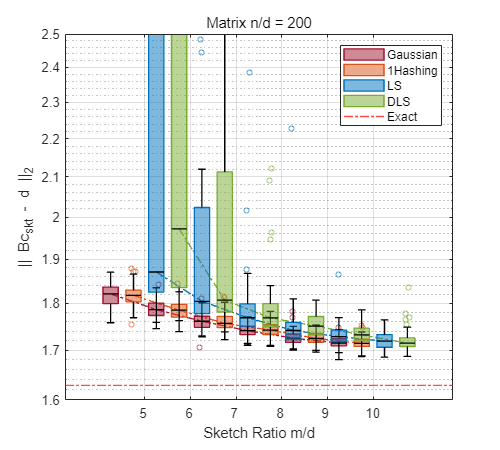

% Residual Zoomed in
figure;
set(gcf,'position',[0, 0, 500, 450])
group_name = {'Gaussian','1Hashing', 'LS', 'DLS'};
color = [0.6350 0.0780 0.1840; 
         0.8500 0.3250 0.0980; 
         0 0.4470 0.7410; 
         0.4660 0.6740 0.1880];

res_zoomed = cellfun(@(x) x(:,4:end), res, 'UniformOutput', false);
h = daboxplot(res_zoomed, ...
              'fill', 1, ...
              'linkline', 1, ...
              'legend', group_name, ...
              'boxalpha', 0.5, ...
              'mean', 0, ...
              'scatter', 0, ...
              'outliers', 1, ...
              'outsymbol', 'o', ...
              'boxwidth', 2.5, ...
              'boxspacing', 1.5, ...
              'colors', color, ...
              'xtlabels' , 5:10);

p = yline(exact_problem.res, ...
          'r-.', 'LineWidth', 1, ...
          'DisplayName', 'Exact');

box on; grid on;
ylim([1.6 2.5]);
set(gca, 'YScale', 'log');
set(h.ln, 'LineStyle', '-.', 'LineWidth', 1);
set(h.md, 'LineWidth', 1);
set(h.lg, 'Location', 'northeast'); 

for i = 1:length(group_name)
    hScatter = h.ot(:,i);
    for j = 1:length(hScatter) 
        set(h.ot(j,i), 'CData', color(i,:));
        set(h.bx(j,i), 'LineWidth', 1, 'EdgeColor', color(i,:));
    end
end

xlabel("Sketch Ratio m/d");
ylabel("|| Bc_{skt} - d ||_2");
title("Matrix n/d = 200"); 

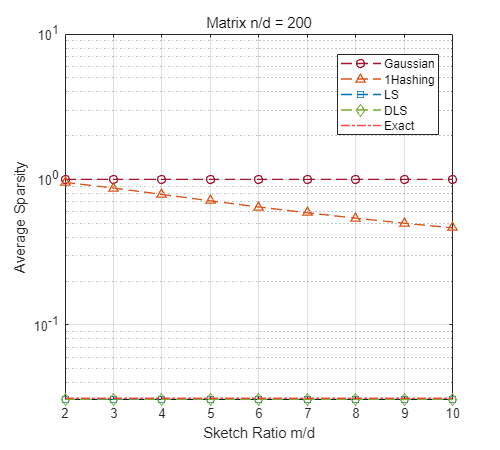

% sparsity
figure;
set(gcf,'position',[0, 0, 500, 450])
group_name = {'Gaussian','1Hashing', 'LS', 'DLS'};
linetype = {'--o', '--^', '--square', '--diamond'};
linecolor = {"#A2142F", "#D95319", 	"#0072BD", 	"#77AC30"};

color = [0.6350 0.0780 0.1840; 
         0.8500 0.3250 0.0980; 
         0 0.4470 0.7410; 
         0.4660 0.6740 0.1880];

av_sparsity = cellfun(@(x) mean(x), sparsity, 'UniformOutput', false);
h = semilogy(skt_ratios, av_sparsity{1}, linetype{1}, ...
             skt_ratios, av_sparsity{2}, linetype{2}, ...
             skt_ratios, av_sparsity{3}, linetype{3}, ...
             skt_ratios, av_sparsity{4}, linetype{4});
p = yline(exact_problem.sparsity, ...
          'r-.', 'LineWidth', 1, ...
          'DisplayName', 'Exact');
for i = 1:4
    h(i).Color = linecolor{i};
    h(i).LineWidth = 1;
end

box on; grid on;

ylim([0 10]);
legend('Gaussian','1Hashing', 'LS', 'DLS', 'Exact',...
       'Location','best');
xlabel("Sketch Ratio m/d");
ylabel("Average Sparsity");
title("Matrix n/d = 200"); %1000

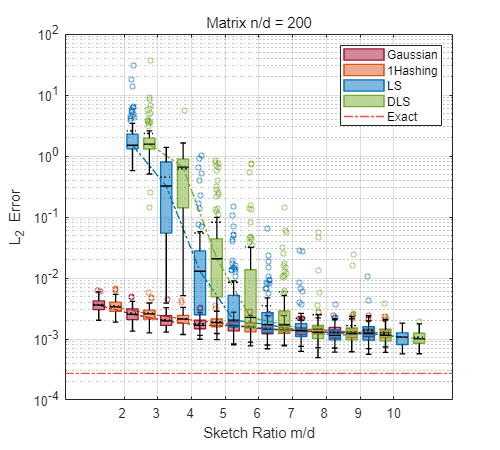

% L2
figure;
set(gcf,'position',[0, 0, 500, 450])
group_name = {'Gaussian','1Hashing', 'LS', 'DLS'};
color = [0.6350 0.0780 0.1840; 
         0.8500 0.3250 0.0980; 
         0 0.4470 0.7410; 
         0.4660 0.6740 0.1880];

h = daboxplot(L2, ...
              'fill', 1, ...
              'linkline', 1, ...
              'legend', group_name, ...
              'boxalpha', 0.5, ...
              'mean', 1, ...
              'scatter', 0, ...
              'outliers', 1, ...
              'outsymbol', 'o', ...
              'boxwidth', 2.5, ...
              'boxspacing', 1.5, ...
              'colors', color, ...
              'xtlabels' , 2:10);

p = yline(exact_problem.L2, ...
          'r-.', 'LineWidth', 1, ...
          'DisplayName', 'Exact');
box on; grid on;

%ylim([0.00068 0.5]);
set(gca, 'YScale', 'log');
set(h.ln, 'LineStyle', '-.', 'LineWidth', 1);
set(h.md, 'LineWidth', 1);
set(h.mn, 'LineWidth', 1);
set(h.lg, 'Location', 'northeast'); 
% set(h.lg, 'Position', [0.7, 0.7, 0.01, 0.01]); 

for i = 1:length(group_name)
    hScatter = h.ot(:,i);
    for j = 1:length(hScatter) 
        set(h.ot(j,i), 'CData', color(i,:));
        set(h.bx(j,i), 'LineWidth', 1, 'EdgeColor', color(i,:));
    end
end

xlabel("Sketch Ratio m/d");
ylabel("L_2 Error");
title("Matrix n/d = 200"); %1000

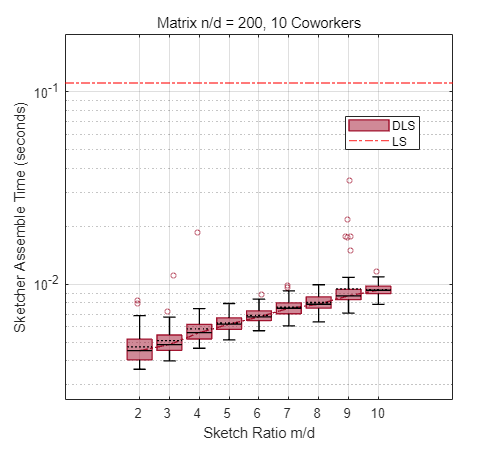

% Time to construct DLS
figure;
set(gcf,'position',[0, 0, 500, 450])
color = [0.6350 0.0780 0.1840; 
         0.8500 0.3250 0.0980; 
         0 0.4470 0.7410; 
         0.4660 0.6740 0.1880];

h = daboxplot(Sketchers{4}.lev_time, ...
              'fill', 1, ...
              'linkline', 1, ...
              'legend', {'DLS'}, ...
              'boxalpha', 0.5, ...
              'mean', 1, ...
              'scatter', 0, ...
              'outliers', 1, ...
              'outsymbol', 'o', ...
              'boxwidth', 2.5, ...
              'boxspacing', 1.5, ...
              'colors', color, ...
              'xtlabels' , 2:10);

p = yline(exact_lev_time, ...
          'r-.', 'LineWidth', 1, ...
          'DisplayName', 'LS');
box on; grid on;

ylim([0.0025 0.2]);
set(gca, 'YScale', 'log');
set(h.ln, 'LineStyle', '-.', 'LineWidth', 1);
set(h.md, 'LineWidth', 1);
set(h.mn, 'LineWidth', 1);
set(h.lg, 'Location', 'northeast'); 
set(h.lg, 'Position', [0.76, 0.7, 0.01, 0.01]); 

for j = 1:length(h.ot) 
    set(h.ot(j,1), 'CData', color(1,:));
    set(h.bx(j,1), 'LineWidth', 1, 'EdgeColor', color(1,:));
end

xlabel("Sketch Ratio m/d");
ylabel("Sketcher Assemble Time (seconds)");
title("Matrix n/d = 200, 10 Coworkers"); %1000